clc;
clear all;
close all;

## generate data

run ("Basics.m")

sys =
 
                 1.3 s + 1.333
  --------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



fb = 2.4327

sysd =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0012   -0.0010   -0.0003


d =     1.0000   -3.4807    4.5802   -2.6968    0.5991


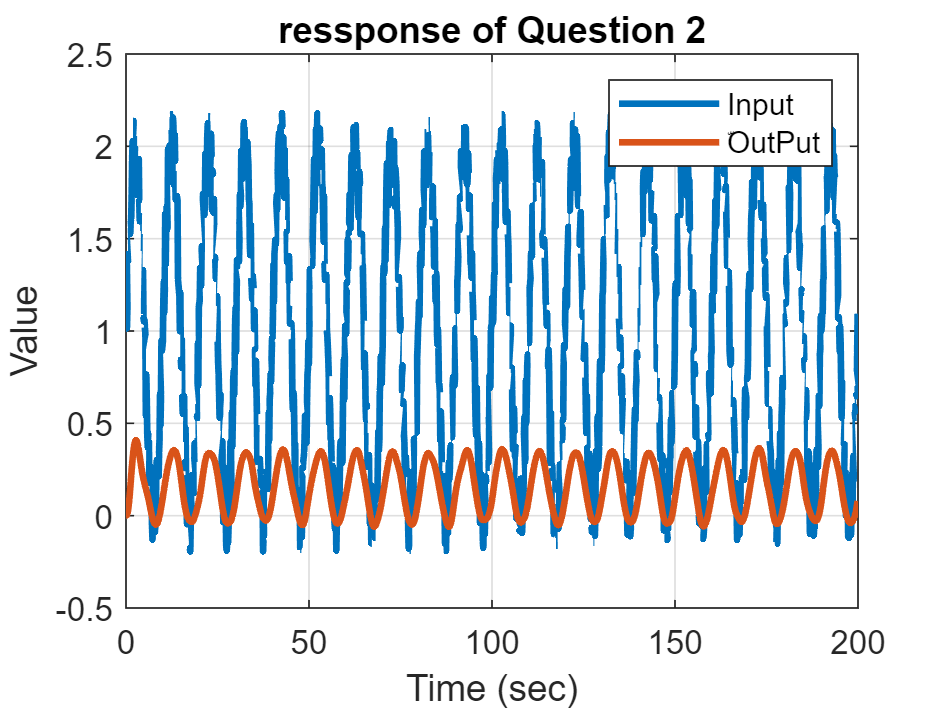

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/20 , tfinal ,T_s);%+gensig('sine' , tfinal/50 , tfinal ,T_s)+gensig('square' , tfinal/10 , tfinal ,T_s);

Noise=[1:numel(t)];
Noise(1:10) = ones(1,10)';
for i=4:1:numel(t)
    Noise(i)=+0.4*Noise(i-1)+0.75*Noise(i-2)-0.15*Noise(i-3);
end
Noise2=-0.2+(0.2+0.2)*rand(numel(t),1);
u=u+Noise'+Noise2;

y = lsim(sysd  ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Input' , 'ّOutPut') ;

## recursive least esquare estimation

N = numel(y) ;
%choose number of parameters
Parameters_in_den=4

Parameters_in_den = 4

Parameters_in_num=4

Parameters_in_num = 4

Parameters_in_noise=3

Parameters_in_noise = 3

Nv=Parameters_in_num+Parameters_in_den+Parameters_in_noise;
P = 1e12*eye(Nv) ;
theta=[Nv,N]

theta =           11        1549


theta(1:Nv,1:30) = 5*ones(Nv,30) ;
e=[numel(y),1]

e =         1549           1


e=zeros(numel(y),1)

e =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


phi=[];
Eror=zeros(1,N)

Eror =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


tic
for i = (max(Parameters_in_num,Parameters_in_den+Parameters_in_noise))+1:N
    phi(:,i) = [[y(i-1:-1:i-Parameters_in_den)]' , [u(i-1:-1:i-Parameters_in_num)]' , [e(i-1:-1:i-Parameters_in_noise)]']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 
    Eror(i)=(Eror(i-1)+(y(i)-phi(:,i)'*theta(:,i))^2);
end

Bode

ident_dis = tf(theta((Parameters_in_num+1):(end-Parameters_in_noise),end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
  0.0004236 z^3 + 0.001167 z^2 - 0.000997 z - 0.0003069
  -----------------------------------------------------
      z^4 - 3.481 z^3 + 4.58 z^2 - 2.697 z + 0.5991
 
Sample time: 0.12914 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
  3.925e-11 s^3 - 2.395e-08 s^2 + 1.3 s + 1.333
  ---------------------------------------------
  s^4 + 3.967 s^3 + 8.41 s^2 + 10.62 s + 8.756
 
Continuous-time transfer function.



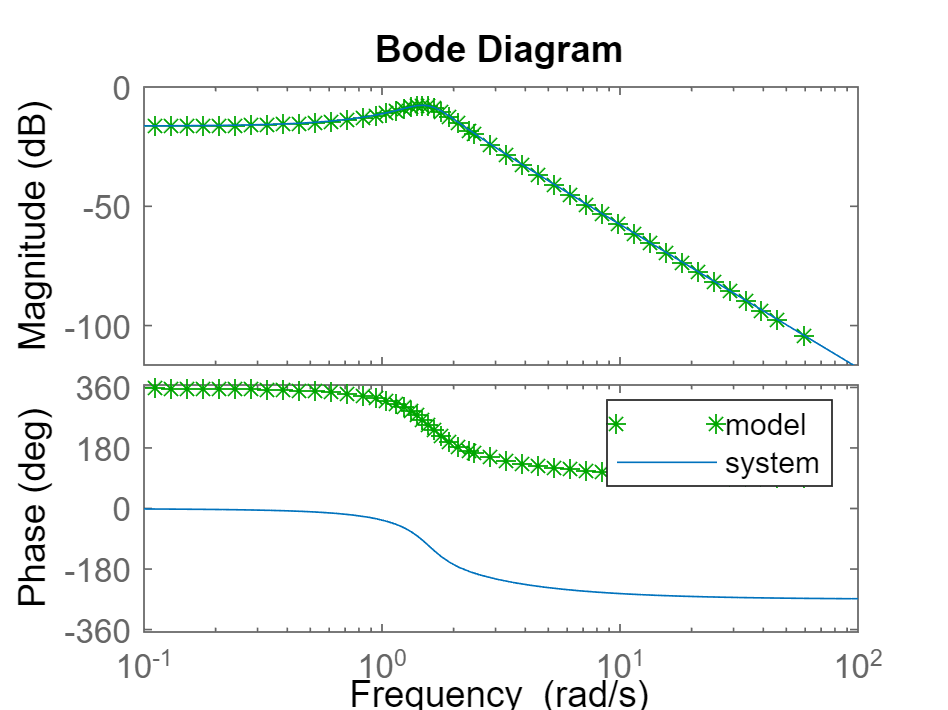

bode(ident_analog ,'g*',sys )
legend('model ','system')

RLS Convergence

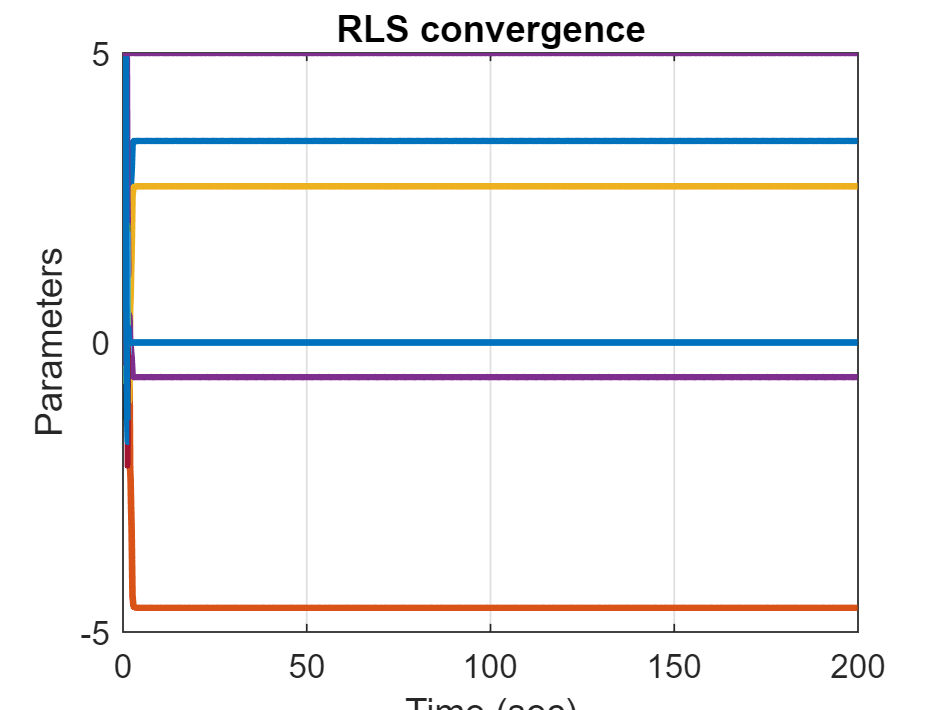

plot(t , theta(:,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence') ;
grid on

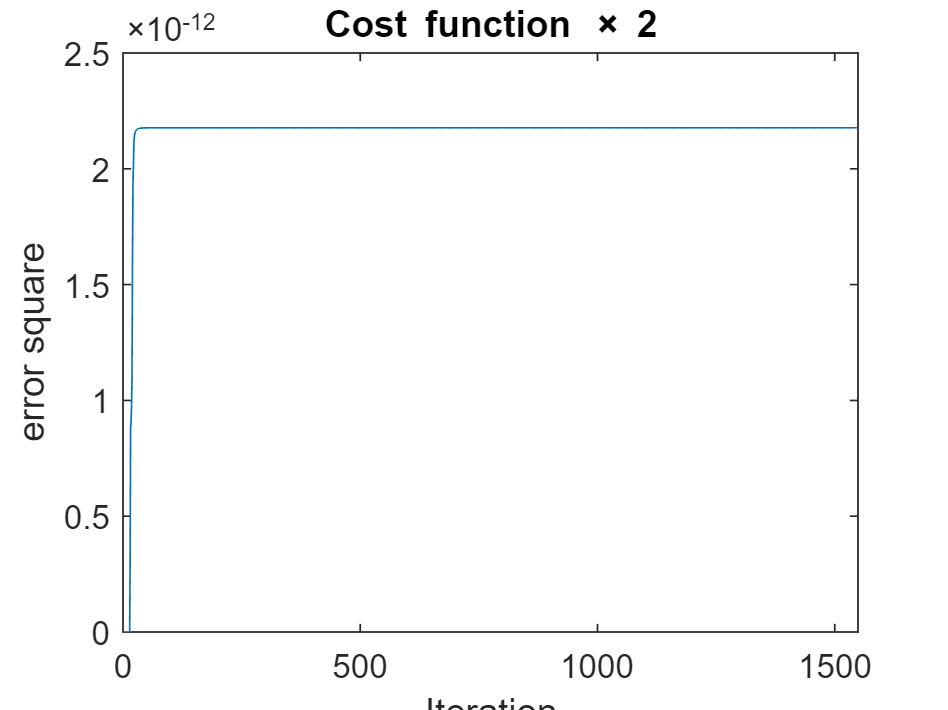

plot(1:1:N,Eror)
xlabel('Iteration') ;
ylabel('error square') ;
title('Cost function \times 2') ;

tfinal=1000;
T_s=T_s

T_s = 0.1291

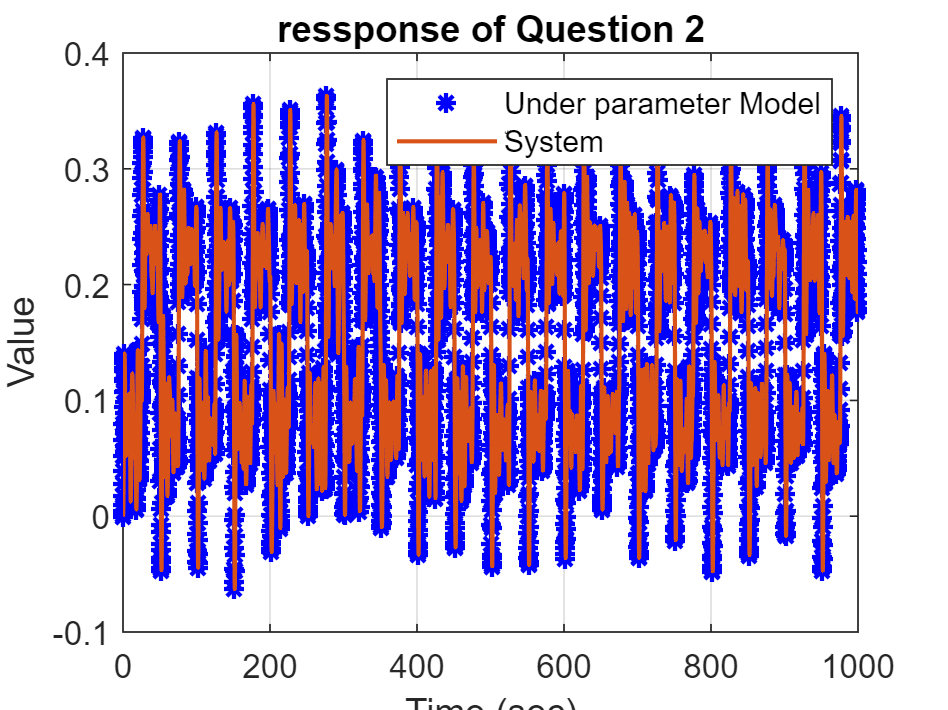

t = 0:T_s:tfinal;
u = gensig('square' , tfinal/20 , tfinal ,T_s);
u = u+rand(numel(t),1);
y = lsim(sysd,u ,t);

y_model = lsim(ident_dis ,u ,t);

plot(t,y_model ,'b*',t , y ,'LineWidth',1.25) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 2') ;
grid on
legend('Under parameter Model' , 'ّSystem') ;